# Train a Network for Split Sequence for Multiple Trajectories

clc
clear
close all
% Program Functions
todayDate = datestr(datetime('today'), 'yyyy-mm-dd');
doTrain = false;
newShuffle = true;

Prepare Data

load('Data/SimulationData/apf_ally_turn.mat','apf_pq_r4')

% Transpose the elements in the dataset from a shape of 3xn to nx3, make it
% the same as the MATLAB example
raw_data = cell(4000,2);
for i = 1:size(apf_pq_r4, 1)
    for j = 1:size(apf_pq_r4, 2)
        % Transpose the 3xN matrix to Nx3
        apf_pq_r4{i, j} = apf_pq_r4{i, j}';
        raw_data{i,j} = apf_pq_r4{i,j}(:,1:4);
    end
end
numObservations = size(raw_data,1);

Plot a few trajectories 

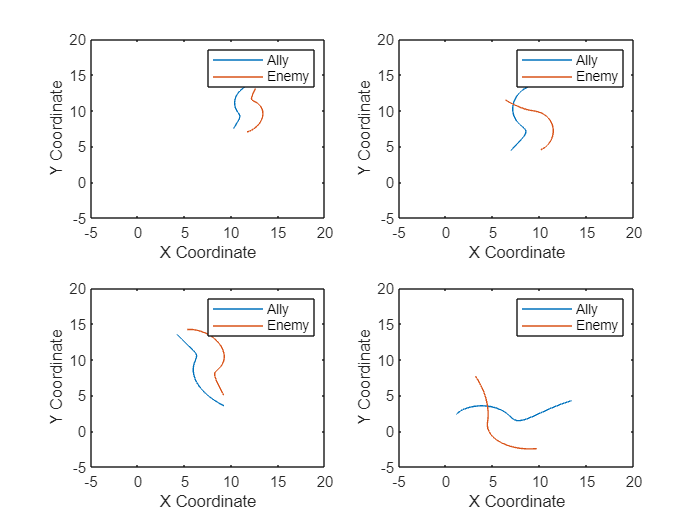

% Plot the trajectory first
for i = 1:4
    subplot(2, 2, i);
    allydata = raw_data{i,1};
    enemydata = raw_data{i,2};
    ally_coord = allydata(:,1:2);
    enemy_coord = enemydata(:,1:2);
    plot(ally_coord(:,1), ally_coord(:,2))
    hold on
    plot(enemy_coord(:,1), enemy_coord(:,2))
    xlim([-5,20])
    ylim([-5,20])
    xlabel('X Coordinate'); % Label for x-axis
    ylabel('Y Coordinate'); % Label for y-axis
    legend('Ally', 'Enemy'); % Add legend
    hold off
end

% Find logical array indicating which cells have m > 100
isLarge = cellfun(@(x) size(x, 1) > 100, raw_data(:,1));

% Extract cells that meet the condition into a new cell array
longTrajectory = raw_data(isLarge,:);


Split the trajectories into the format of moving window input and outputs

offset = 9;
validWindows = false(offset, 1);

XArray = zeros(offset+1,3);
XAll = {};
TAll = {};
allData = {};
k = 1; % Index for XAll, storing input and output data
for n = 1:size(longTrajectory,1)

    allydata = longTrajectory{n,1};
    enemydata = longTrajectory{n,2};
    % enemyInitial = enemydata(1,:);
    % XArray = [enemyInitial; allydata(1:offset-1,:)];
    % TArray = enemydata(offset,1:2);

    numWindows = size(allydata, 1) - offset;
    validWindows = false(numWindows, 1);
    
    % XAll{1,n} = XArray;
    % TAll{1,n} = TArray;
    
    for t = 1:numWindows-1
        
        windowLastColumn = allydata(t:t+offset, end); % Extract the last column of the window
        if all(abs(windowLastColumn - 0) > 0.001) % Check if all elements are non-zero
            validWindows(t) = true;
            XAll{k,1} = [allydata(t:t+offset,1:3)];
            TAll{k,1} = enemydata(t+offset+1,1:2);
            allData{k,1} = XAll{k,1};
            allData{k,2} = TAll{k,1};
            k = k + 1;
        end
       
    end
end


Shuffle the data before training

if newShuffle
    randOrder = randperm(size(XAll,1));
    % save('Data/TrainingData/shuffleOrder_apf.mat','randOrder')
    newShuffle = false;
else
    load('Data/TrainingData/shuffleOrder_apf.mat','randOrder')
end

shuffledData = allData(randOrder,:);

Split the data before training

totalSamples = size(shuffledData,1);
iTrain = 1:floor(0.7*totalSamples);
iVal = floor(0.7*totalSamples)+1 : floor(0.9*totalSamples);
iTest = floor(0.9*totalSamples) + 1 : totalSamples;

XTrain = shuffledData(iTrain,1);
XVal = shuffledData(iVal,1);
XTest= shuffledData(iTest,1);

TTrain = cell2mat(shuffledData(iTrain,2));
TVal = cell2mat(shuffledData(iVal,2));
TTest= cell2mat(shuffledData(iTest,2));


Normalize the data

% Normalize
% muX_train = mean(cell2mat(XTrain));
% sigmaX_train = std(cell2mat(XTrain),0);
% 
% muT_train = mean(TTrain);
% sigmaT_train = std(TTrain,0);
% 
% for n = 1:numel(XTrain)
%     XTrain_norm{n} = (XTrain{n} - muX_train) ./ sigmaX_train;
%     TTrain_norm(n,:) = (TTrain(n,:) - muT_train) ./ sigmaT_train;
% end
% 
% for n = 1:numel(XVal)
%     XVal_norm{n} = (XVal{n} - muX_train) ./ sigmaX_train;
%     TVal_norm(n,:) = (TVal(n,:) - muT_train) ./ sigmaT_train;
% end
% 
% for n = 1:numel(XTest)
%     XTest_norm{n} = (XTest{n} - muX_train) ./ sigmaX_train;
%     TTest_norm(n,:) = (TTest(n,:) - muT_train) ./ sigmaT_train;
% end


Train the network

numChannels = 3;
numOutputs = 2;

if doTrain
    layers = [...
        sequenceInputLayer(numChannels)
        % lstmLayer(100,'OutputMode','sequence')
        % % lstmLayer(100,'OutputMode','sequence')
        % dropoutLayer(0.2)
        % lstmLayer(75, "OutputMode","sequence")
        % dropoutLayer(0.25)
        lstmLayer(32, 'OutputMode', 'sequence')
        dropoutLayer(0.2)
        lstmLayer(128, 'OutputMode', 'last')
        fullyConnectedLayer(numOutputs)
        ];

    % layerGraph(layers)
    options = trainingOptions('adam', ...
        'ExecutionEnvironment','gpu',...
        MaxEpochs=500, ...
        MiniBatchSize=128,...
        InitialLearnRate=0.001,...
        LearnRateSchedule='piecewise',...
        LearnRateDropPeriod=100,...
        LearnRateDropFactor=0.2,...
        SequencePaddingDirection='left',...
        Shuffle='every-epoch',...
        GradientThreshold=0.5,...
        Verbose=true,...
        Plots='training-progress',...
        ValidationData={XVal,TVal});
    %% Train Recurrent Neural Network
    multiSliceNet_mw9 = trainnet(XTrain, TTrain, layers, 'mse',options);
    save('Data/Network/Sliced_strict_apf.mat','multiSliceNet')
end

% load('Data/Network/Sliced_strict_apf_mw9.mat','multiSliceNet_mw9')

Xmoving_window = zeros(offset,3);
Tmoving_window = zeros(1,2);
XTrajTest = {};
TTrajTest = {};

numLongTrajectory = size(longTrajectory,1);
testIdx = 2;
testTrajectory = longTrajectory(testIdx,:);
allydata = testTrajectory{1};
enemydata = testTrajectory{2};
enemyInitial = enemydata(1,1:3);

numTimeSteps = size(allydata,1);
numPredictionTimeSteps = numTimeSteps - offset;
j = 1;

Y_norm= nan(numPredictionTimeSteps,2); % Out of plotting range
Y_reg = Y_norm;

% FILO filter
% Define filter parameters
filo_length = 5;  % Length of the moving average window
Y_filter = nan(size(Y_reg));  % Preallocate filtered output
buffer = zeros(filo_length,2);  % Circular buffer for moving average
buffer_sum = [0,0];  % Sum of values in the buffer



for t = 1:numPredictionTimeSteps-1
    % If all ally inputs have a nonzero angular velocity,
    % then store as an input data
    Xmoving_window = allydata(t:t+offset,1:3);
    Tmoving_window = enemydata(t+offset+1,1:2);
    XTrajTest{j} = Xmoving_window;
    TTrajTest{j} = Tmoving_window;
    [Y_reg(t,:),state] = predict(multiSliceNet_mw9,XTrajTest{j});
    multiSliceNet_mw9.resetState();
    j = j + 1;
    

    if t <= filo_length
        buffer(t,:) = Y_reg(t,:);
        buffer_sum = sum(buffer,1);
        Y_filter(t,:) = buffer_sum / t;  % For the first few points
    else
        buffer(1:filo_length-1,:) = buffer(2:filo_length,:);
        buffer(end,:) = Y_reg(t,:);
        buffer_sum = sum(buffer,1);
        Y_filter(t,:) = buffer_sum / filo_length;  % Full window average
        
    end
    
end

Unrecognized function or variable 'multiSliceNet_mw9'.

% Y_reg = Y_norm .* sigmaT_train + muT_train;

numWindows = size(allydata, 1) - offset;
validWindows = false(numWindows, 1);

angular_velocity = allydata(:,4);
non_zero_dphi = abs(angular_velocity) > 0.001;
section_start = find(diff([0;non_zero_dphi;0]) == 1);
section_end = find(diff([0;non_zero_dphi;0]) == -1);

plot_idx = (section_start + offset ) <= length(non_zero_dphi);
section_start = section_start(plot_idx);
section_end = section_end(plot_idx);

if section_end(end) > length(non_zero_dphi)
    section_end(end) = length(non_zero_dphi);
end


% Find the coordinates based on the index

start_x = allydata(section_start,1);
start_y = allydata(section_start,2);
end_x = allydata(section_end,1);
end_y = allydata(section_end,2);

figure;
c = linspace(1,10, length(Y_reg));
scatter(enemydata(offset+1:end,1), enemydata(offset+1:end,2),[],c, ...
    'DisplayName','Actual Enemy Locations');
hold on
% 
% scatter(enemydata(offset+section_start,1),enemydata(offset+section_start,2),80,'magenta','filled','o', ...
%     'DisplayName','Non-straight Starting Point')
% plot(allydata(1:offset,1), allydata(1:offset,2),'b','LineWidth',2,'DisplayName','Ally')
scatter(enemydata(1,1),enemydata(1,2),60,'filled','d', ...
    'DisplayName','Enemy Start Point','MarkerFaceColor',[0.4940 0.1840 0.5560])
plot(allydata(:,1),allydata(:,2),'Color',[0 0.4470 0.7410],'LineWidth',2,'DisplayName','Ally Trajectory')
plot(enemydata(:,1),enemydata(:,2),'--','DisplayName','Enemy Trajectory')
% plot(allydata(1:offset,1), allydata(1:offset,2),'g','LineWidth',2, ...
%     'DisplayName','First Input (Ally)')
scatter(allydata(1,1),allydata(1,2),60,'filled','d','DisplayName','Ally Start Point','MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter(Y_filter(:,1), Y_filter(:,2),[],c,'filled','DisplayName','Predicted Enemy Locations')
% first_not_straight = XTrajTest{section_start(1)};
% plot(first_not_straight(2:end,1), first_not_straight(2:end,2),'g','LineWidth',2, ...
%     'DisplayName','First Non-straint Input Data')
% scatter(Y_reg(section_start,1),Y_reg(section_start,2),80,'red','filled','o', ...
%     'DisplayName','Non-straight Starting Point')
xlabel("X")
ylabel('Y')
xlim([-5,15])
ylim([-5,15])
colorbar;
colormap("parula");
cb = colorbar;
cb.Label.String = 'Predict Steps';
cb.Limits = [1,10];
cb.Ticks = [1 10];  % Place ticks at the ends of the color bar
cb.TickLabels = {'1', numPredictionTimeSteps};  % Set the labels at these ticks to '1' and '92'
legend('show')
ax = gca;
ax.FontSize = 16;
hold off


figure
plot(allydata(:,1),allydata(:,2))
hold on
plot(allydata(1:75,1),allydata(1:75,2))
plot(enemydata(:,1),enemydata(:,2))
hold off